%syms t
f = 9.27 %flapping frequency

f = 9.2700

T = 1/f

T = 0.1079

phi = 0.762 %flapping amplitude, in m

phi = 0.7620

tau = 0.5

tau = 0.5000

b = 0.4625/2;
U = 10 %m/s U=V

U = 10

S = 0.02584 %m2

S = 0.0258

rho = 1.225

rho = 1.2250

CD_0 = 0.02

CD_0 = 0.0200

W1 = 0.0342

W1 = 0.0342

g = 9.81

g = 9.8100

%expr = @(t) 0.875*cos((-phi/2)*cos(pi*t/(tau*T)))
%integral(expr,0, tau*T) 
%expr1 = 0.875*cos((-phi/2)*cos(pi*t/(tau*T)))
%F = int(expr1,t,[0 tau*T]) 
%Fvpa = vpa(F)

%f = 7.11 %flapping frequency
%T = 1/f
%phi = 0.2109 %flapping amplitude, in m
%tau = 0.5
%expr = @(t) 0.875*cos((-phi/2)*cos(pi*t/(tau*T)))
%integral(expr,0, tau*T) 
%Fvpa = vpa(F)

%syms r
%func = @(r) r.^2.*(4.*r).*(1-r)
%func1 = @(r) r.^2
%a = integral(func1, 0,0.5)
%b = integral(func, 0.5,1)
%a+b
%sqrt(a+b)

A = -0.5*rho*CD_0*U

A = -0.1225

theta = -0.5*phi*cos(pi/(tau*T))

theta = 0.0478

D_prof1 = (3.167*A*U)*(tau*T)

D_prof1 = -0.2093

D_2 = @(t) 1.2295.*A.*b.*cos(cos(theta*t))

D_2 = function_handle with value:
    @(t)1.2295.*A.*b.*cos(cos(theta*t))


%D_pro1 = integral(D_1, 0, T.*tau)
D_prof2 = integral (D_2, 0, tau*T)

D_prof2 = -0.0010

D_prof = sqrt(D_prof1^2 + D_prof2^2)

D_prof = 0.2093

C_D = D_prof/(0.5*rho*U^2*S*tau)

C_D = 0.2644

C_L = (W1*g - D_prof2)/(0.5*rho*U^2*S*tau)

C_L = 0.4252

%m = 0:0.01:0.5;
m = 0.0241

m = 0.0241

g = 9.81

g = 9.8100

S = 0.02736

S = 0.0274

b = 0.4616

b = 0.4616

rho = 1.225

rho = 1.2250

f_eqn = (m.^(3/8))*(g^(1/2))*(b^(-23/24))*(S^(-1/3))*(rho^(-3/8))

f_eqn = 4.9974

St = 0.3

St = 0.3000

ha = (St*U)./(2.*f_eqn)

ha = 0.3002

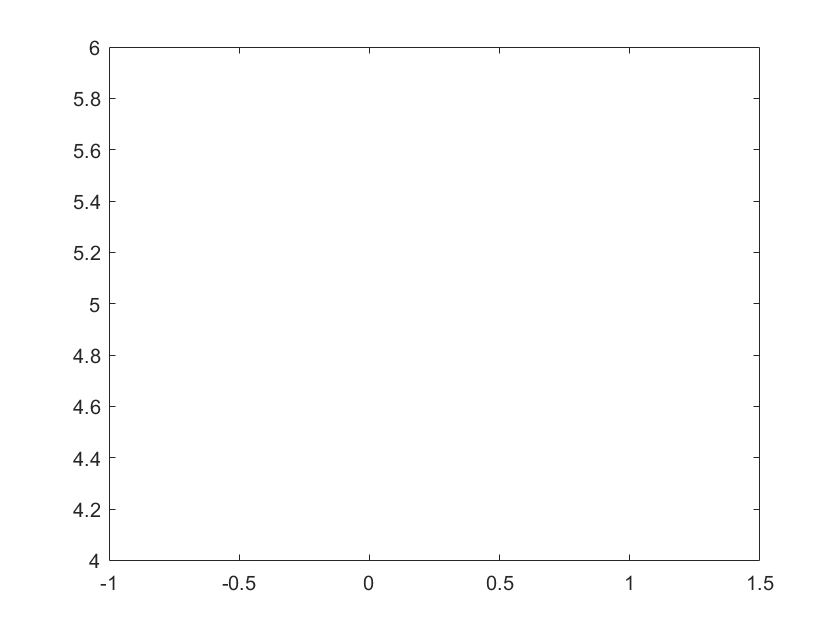

plot(m,f_eqn)

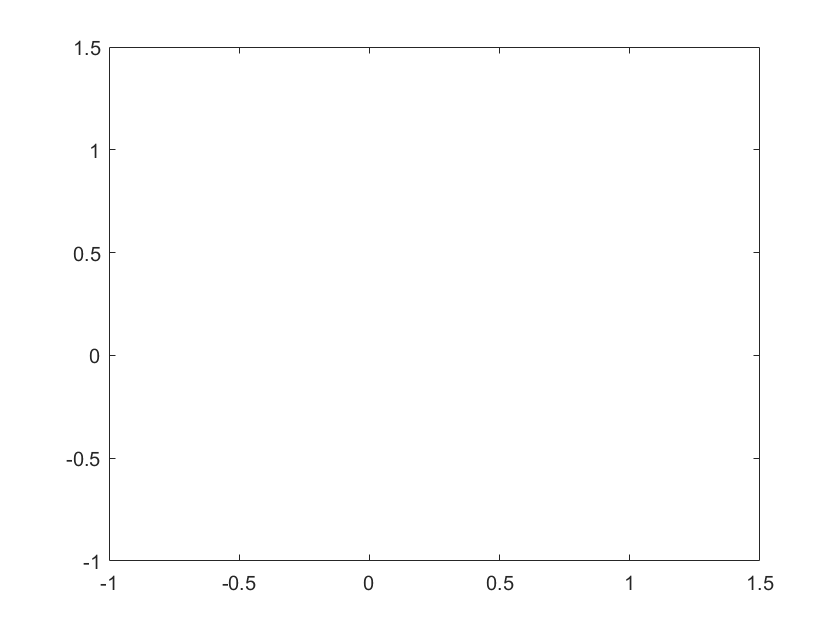

plot(m, ha)